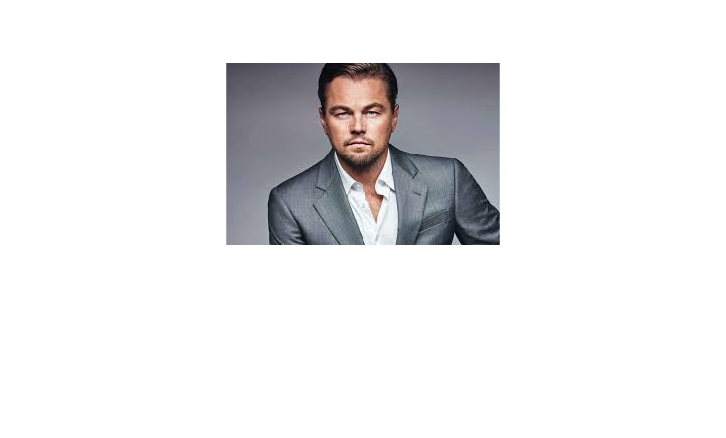

I = imread('C:\Users\surya\OneDrive\_MS RAS AI\2 Fall 2022\MAE 547\Project\leo.jpg');
imshow(I)

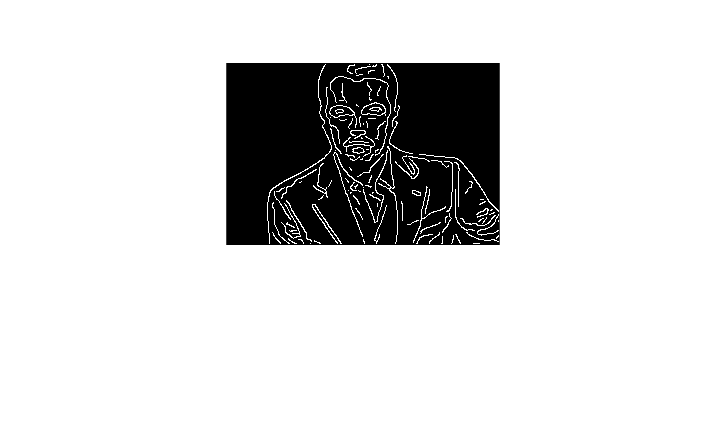

[BW,thre] = edge(rgb2gray(I),'Canny',[0.0813 0.1281]); %エッジ検出
figure, imshow(BW);

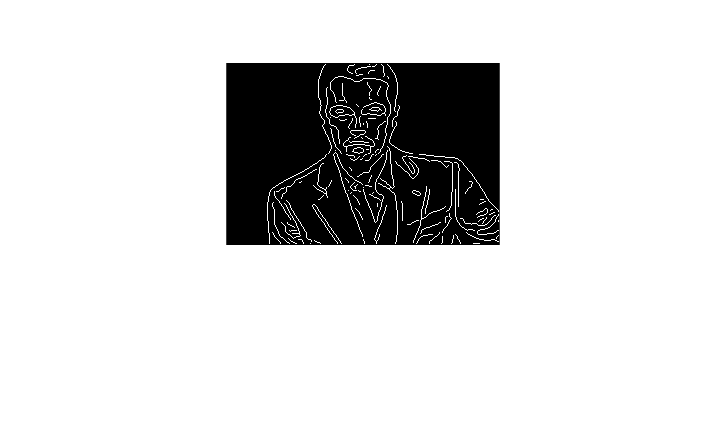

BW2 = bwmorph(BW,'skel',Inf);
figure, imshow(BW2);

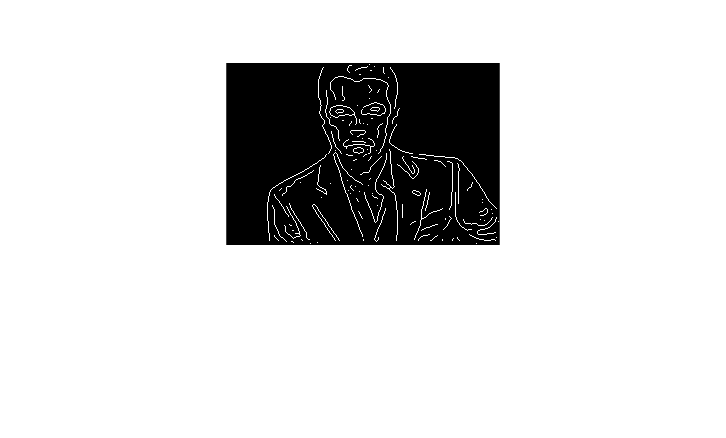

BW3 = bwmorph(BW2,'spur',3);
figure, imshow(BW3);

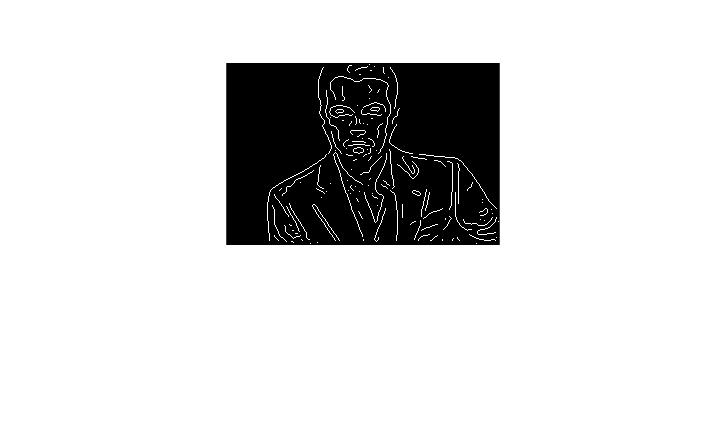

branchPoints = bwmorph(BW3,'branch',1); %枝分かれ位置の検出
branchPoints = imdilate(branchPoints,strel('disk',1));
BW3 = BW3 & ~branchPoints;
figure, imshow(BW3)

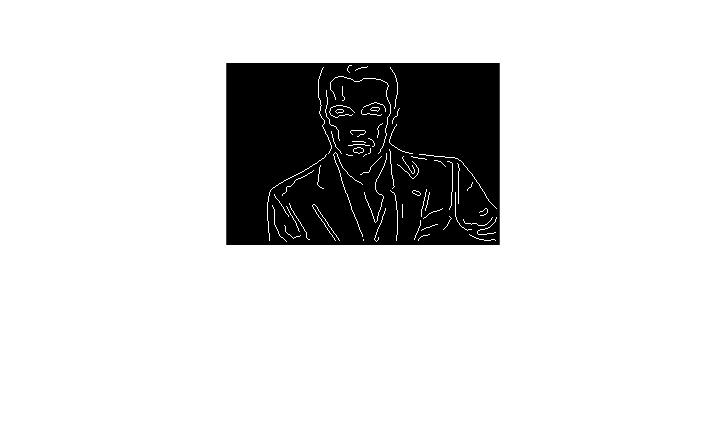

BWseg = bwareaopen(BW3,10);
figure, imshow(BWseg)

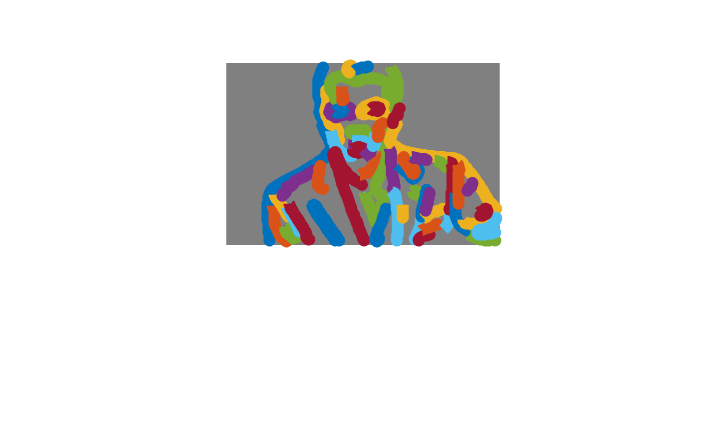

[B,L] = bwboundaries(BWseg,'noholes');
imshow(label2rgb(L, @jet, [.5 .5 .5]))
hold on
for k = 1:length(B)
   boundary = B{k};
   plot(boundary(:,2), boundary(:,1), 'LineWidth', 3)
end

boundary = B{18};
edgeind = find(all(circshift(boundary,1)==circshift(boundary,-1),2),1)

edgeind = 23

boundary = circshift(boundary,-edgeind+1);
boundary = boundary(1:ceil(end/2),:)

boundary =     83   145
    83   144
    83   143
    83   142
    83   141
    82   140
    82   139
    82   138
    82   137
    82   136


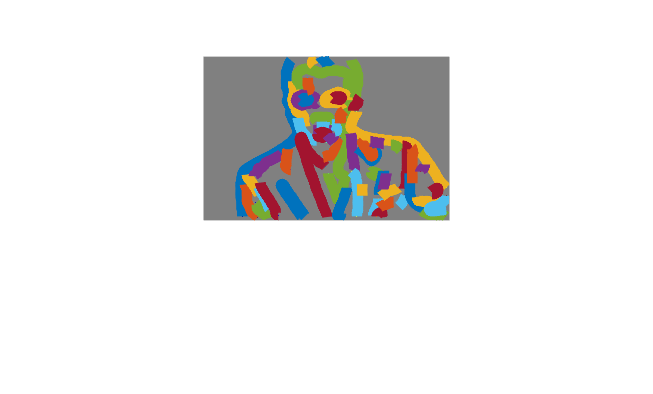

for i = 1:length(B)
    boundary = B{i};
    edgeind = find(all(circshift(boundary,1)==circshift(boundary,-1),2),1);
    if ~isempty(edgeind)
        boundary = circshift(boundary,-edgeind+1);
        boundary = boundary(1:ceil(end/2),:);
    end
    B{i} = boundary;
end
imshow(label2rgb(L, @jet, [.5 .5 .5]))
hold on
for k = 1:length(B)
   boundary = B{k};
   plot(boundary(:,2), boundary(:,1), 'LineWidth', 3)
end

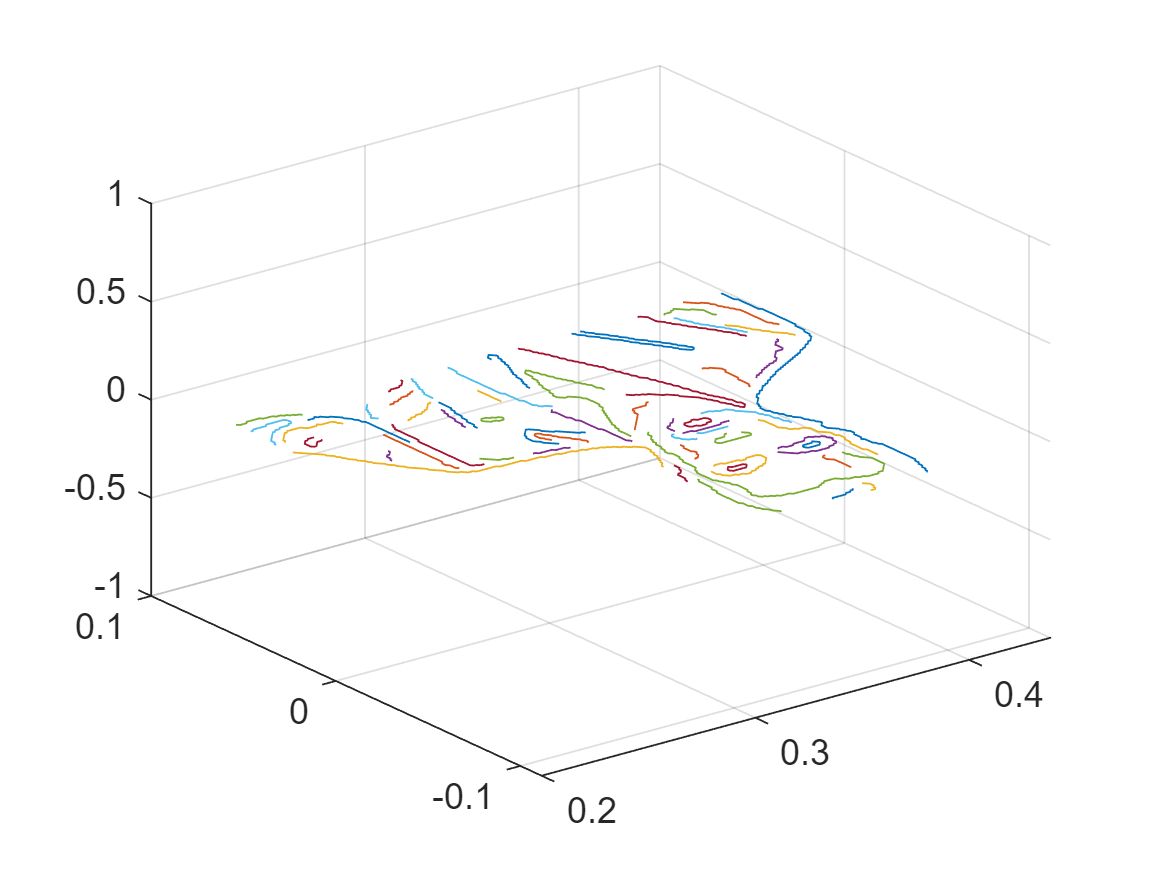

origin = [0.48 -0.229/2]; % 画像の原点の位置
delta = 0.001; % 1ピクセルの長さ
B2 = B;
figure;
for i = 1:length(B)
    b = B{i};
    bx = -b(:,2)*delta+origin(1);
    by = b(:,1)*delta+origin(2);
    bz = zeros(length(bx),1);
    B2{i} = [bx by bz];
    plot3(bx,by,bz); hold on;
end
grid on;